clear all;
close all;

JND = 2.3

JND = 2.3000

location = fullfile('dil_1_12');
ds = imageDatastore(location,'FileExtensions',{'.jpg','.tif','.png'});
lbls = filenames2labels(location,FileExtensions=".jpg")

lbls = 10×1 categorical array
     0 
     100 
     1000 
     10000 
     200 
     2000 
     3000 
     40 
     400 
     4000 


% labels = uint8(length(lbls));

for i = 1:length(lbls)
    filename = string(lbls(i));
    filename(find(filename == '.',1,'last'):end) = []; %remove extensio
%     C = regexp(filename, '_', 'split');
    l = string(filename);
    labels(i) =  str2double(l)*4;
end

w = 10;
h = 10; 
nimage = length(ds.Files);
imDim = [h w];



rsImages = uint8(zeros(h, w, 3, nimage));
aveColor = uint8(zeros(nimage, 3));
for i = 1:nimage
    data = readimage(ds,i); 
    t = imresize(data, imDim);
    rsImages(:, :, :, i) = t;
    aveColor(i, :) = [mean(mean(t(:, :, 1))); mean(mean(t(:, :, 2)));  mean(mean(t(:, :, 3)))];

end


data = [labels' aveColor]

data = 10×4 uint8 matrix
     0   211   214   204
   255   215   218   215
   255   204   205   200
   255   221   215   204
   255   221   223   221
   255   212   213   207
   255   214   213   206
   160   214   217   212
   255   223   227   225
   255   217   214   206


data = sort(data, 'ascend');
lbls = data(:, 1);
aveColor = data(:, 2:end);

de = zeros(nimage, nimage);

for i = 1:nimage
    a = (aveColor(i, :));
    for j = 1:nimage
         b = (aveColor(j, :));
        de(i, j) = imcolordiff(a,b,"Standard","CIEDE2000");%, "isInputLab", true);
%         de(i, j) = deltaE(a,b, "isInputLab", true);
        % if(de(i, j) <= JND)
        %      de(i, j) = 0; 
        % else
        %     de(i, j) = 2;
        % end

    end
end



jndThreshold = 0;

for i = 2:nimage
    j = i -1; 
    a = (aveColor(i, :));
    b = (aveColor(j, :));
    deCount(i) = imcolordiff(a,b,"Standard","CIEDE2000");%, "isInputLab", true);
    
    if(deCount(i) >= JND && jndThreshold ~= 0)
        jndThreshold = lbls(i);
    end
end

% XYZ = rgb2xyz(aveColor)

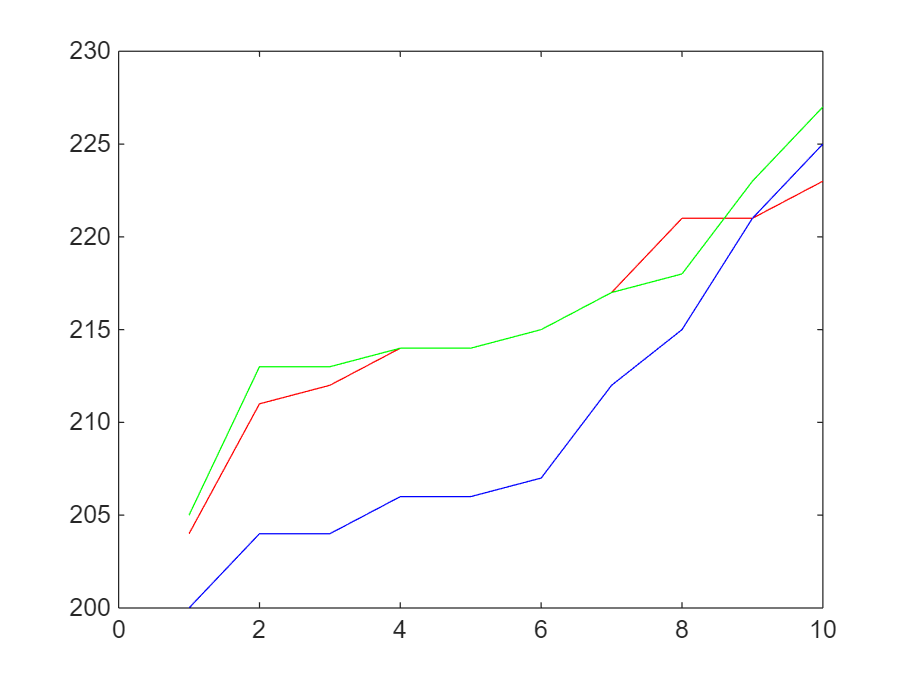

rgbplot(aveColor)


mymap = [0 0 0
    0.1 .75 .9];
maxDE = max(max(de))

maxDE = 5.3399

r = maxDE;

image(de);
colormap(flipud(colormap(jet(6))))
c = colorbar

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [1 7]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


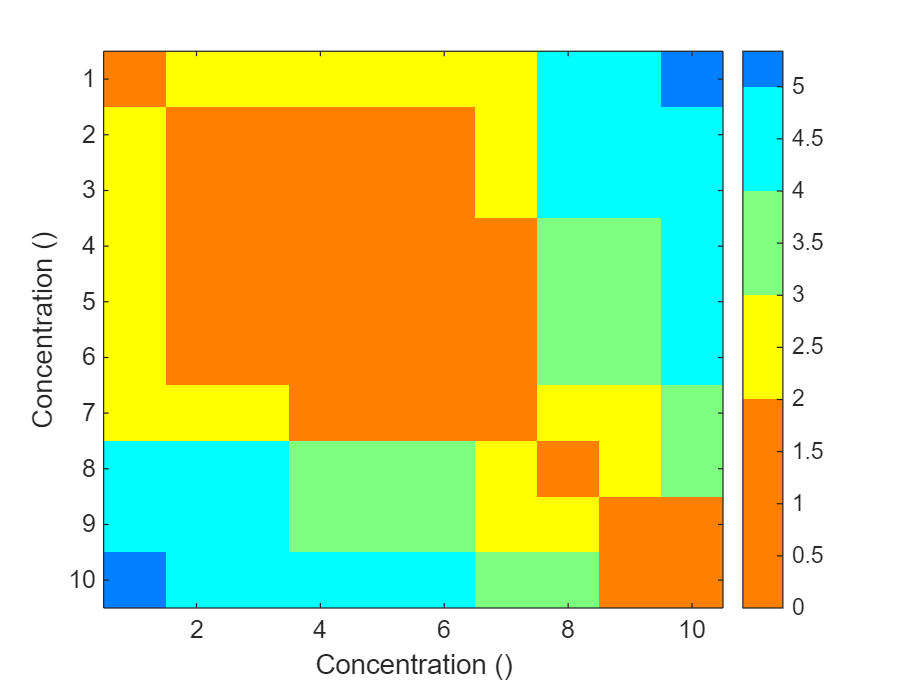

c.Limits = [0 maxDE];
xlabel('Concentration ()')
ylabel('Concentration ()')


image(de);

colormap(mymap)
clim([0 0.9])

  yline(0.5, 'r', 'LineWidth',2);
  yline(1.5, 'r', 'LineWidth',2);
  yline(2.5, 'r', 'LineWidth',2);
  yline(3.5, 'r', 'LineWidth',2);
  yline(4.5, 'r', 'LineWidth',2);
  yline(5.5, 'r', 'LineWidth',2);
  yline(6.5, 'r', 'LineWidth',2);
  yline(7.5, 'r', 'LineWidth',2);
  yline(8.5, 'r', 'LineWidth',2);
  yline(9.5, 'r', 'LineWidth',2);
  yline(10.5, 'r', 'LineWidth',2);
 % 
  xline(0.5, 'r', 'LineWidth',2);
  xline(1.5, 'r', 'LineWidth',2);
  xline(2.5, 'r', 'LineWidth',2);
  xline(3.5, 'r', 'LineWidth',2);
  xline(4.5, 'r', 'LineWidth',2);
  xline(5.5, 'r', 'LineWidth',2);
  xline(6.5, 'r', 'LineWidth',2);
  xline(7.5, 'r', 'LineWidth',2);
  xline(8.5, 'r', 'LineWidth',2);
  xline(9.5, 'r', 'LineWidth',2);
  xline(10.5, 'r', 'LineWidth',2);
c = colorbar

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [1 3]
    FontSize: 9
    Position: [0.8298 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


c.Limits = [0 r];
tick_val = 1:10;
tick_labels = arrayfun(@num2str, unique(labels), 'UniformOutput', 0)

tick_labels = 1×10 cell array
    {'0'}    {'160'}    {'400'}    {'800'}    {'1600'}    {'4000'}    {'8000'}    {'12000'}    {'16000'}    {'40000'}


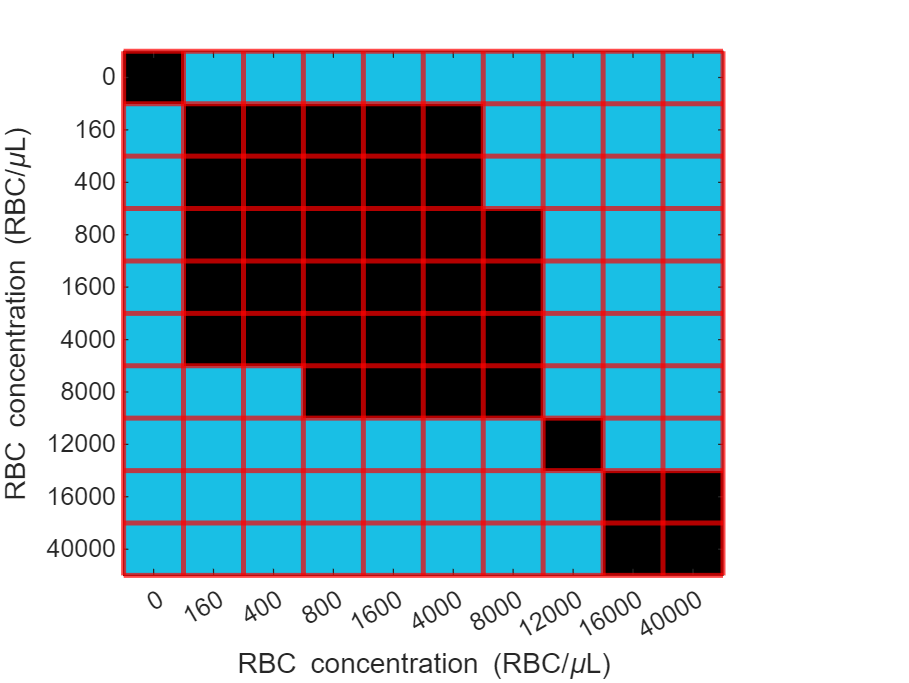

set(colorbar,'visible','off')
yticks(tick_val)
xticks(tick_val)
yticklabels(tick_labels);
xticklabels(tick_labels);
set(gca,'TickLabelInterpreter', 'tex')
xlabel('RBC concentration (RBC/\muL)')
ylabel('RBC concentration (RBC/\muL)')

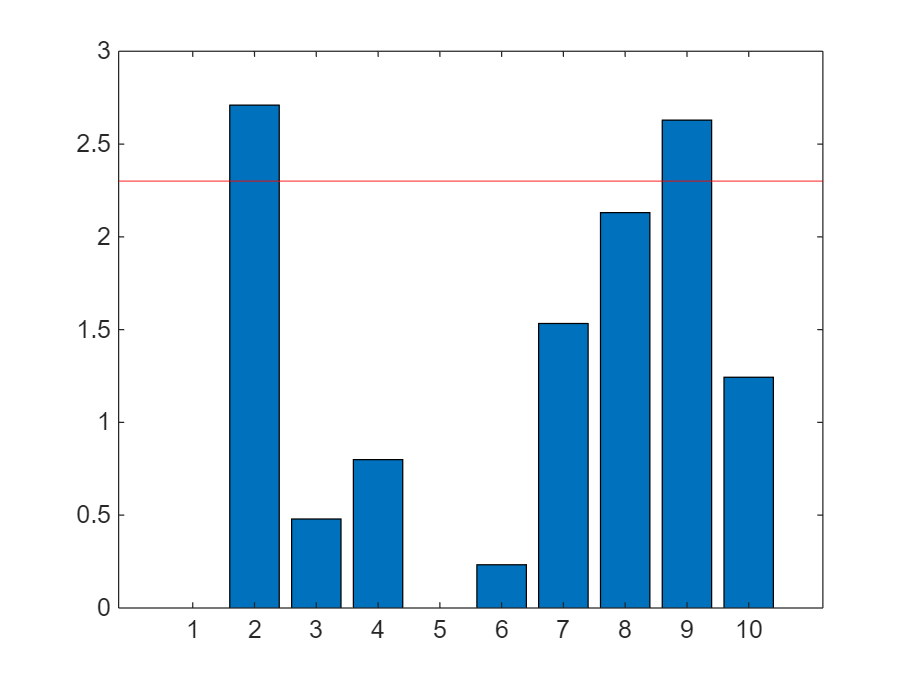

figure; 
bar(deCount); hold on, 
yline(JND, 'r');
hold off;

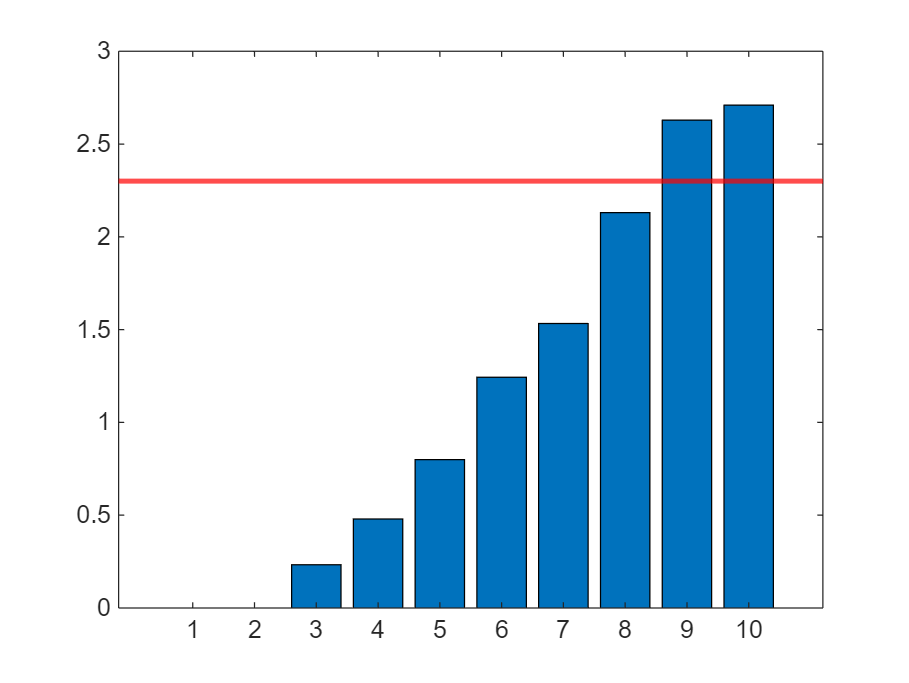

dc = sort(deCount, "ascend");
xCenter = 4;
yCenter = JND; 
figure; 

bar(dc); hold on, 
% plot(xCenter, yCenter, 'ro', 'LineWidth', 2, 'MarkerSize', 16);
yline(JND, 'r', LineWidth=2);
% xline(xCenter, 'g');
hold off;

%{

clear all;
close all;

JND = 2.3


1_6 Dilution

location = fullfile('dil_1_6');
ds = imageDatastore(location,'FileExtensions',{'.jpg','.tif','.png'});
lbls = filenames2labels(location,FileExtensions=".jpg")

% labels = uint8(length(lbls));

for i = 1:length(lbls)
    filename = string(lbls(i));
    filename(find(filename == '.',1,'last'):end) = []; %remove extensio
%     C = regexp(filename, '_', 'split');
    l = string(filename);
    labels(i) =  str2double(l);
end

w = 10;
h = 10; 
nimage = length(ds.Files);
imDim = [h w];



rsImages = uint8(zeros(h, w, 3, nimage));
aveColor = uint8(zeros(nimage, 3));
for i = 1:nimage
    data = readimage(ds,i); 
    t = imresize(data, imDim);
    rsImages(:, :, :, i) = t;
    aveColor(i, :) = [mean(mean(t(:, :, 1))); mean(mean(t(:, :, 2)));  mean(mean(t(:, :, 3)))];

end


data = [labels' aveColor]
data = sort(data, 'ascend');
lbls = data(:, 1);
aveColor = data(:, 2:end);

de = zeros(nimage, nimage);

for i = 1:nimage
    a = (aveColor(i, :));
    for j = 1:nimage
         b = (aveColor(j, :));
        de(i, j) = imcolordiff(a,b,"Standard","CIEDE2000");%, "isInputLab", true);
%         de(i, j) = deltaE(a,b, "isInputLab", true);
    end
end



jndThreshold = 0;

for i = 2:nimage
    j = i -1; 
    a = (aveColor(i, :));
    b = (aveColor(j, :));
    deCount(i) = imcolordiff(a,b,"Standard","CIEDE2000");%, "isInputLab", true);
    
    if(deCount(i) >= JND && jndThreshold ~= 0)
        jndThreshold = lbls(i);
    end
end




maxDE = max(max(de))
minDE = min(min(de(de>0)))

m = int8(maxDE);
colormap(parula(m));

% XYZ = rgb2xyz(aveColor)
rgbplot(aveColor)



image(de);
c = colorbar
c.Limits = [0 maxDE];
xlabel('Concentration ()')
ylabel('Concentration ()')



figure; 
bar(deCount); hold on, 
yline(JND, 'r');
hold off;


dc = sort(deCount, "ascend");
xCenter = 4;
yCenter = JND; 
figure; 

bar(dc); hold on, 
% plot(xCenter, yCenter, 'ro', 'LineWidth', 2, 'MarkerSize', 16);
yline(JND, 'r', LineWidth=2);
% xline(xCenter, 'g');
hold off;


%}
